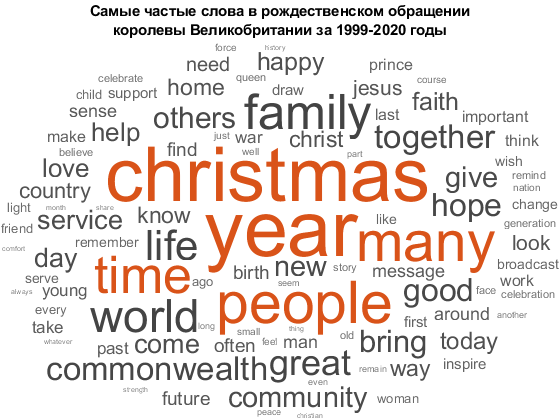

%doc_struct.gb.preproc_text = strings(size(doc_struct.gb.transcript));

doc_struct.gb.preproc_text = preprocessText(doc_struct.gb.transcript);

remove_word_arr = [
    "the" "say" "second" "own"
];

doc_struct.gb.preproc_text = removeWords(doc_struct.gb.preproc_text, remove_word_arr);

doc_struct.gb.tokenized = tokenizedDocument(doc_struct.gb.preproc_text);

doc_struct.gb.bag = bagOfWords(doc_struct.gb.preproc_text);

wordcloud(doc_struct.gb.bag);

title({'Самые частые слова в рождественском обращении', ...
    'королевы Великобритании за 1999-2020 годы'})

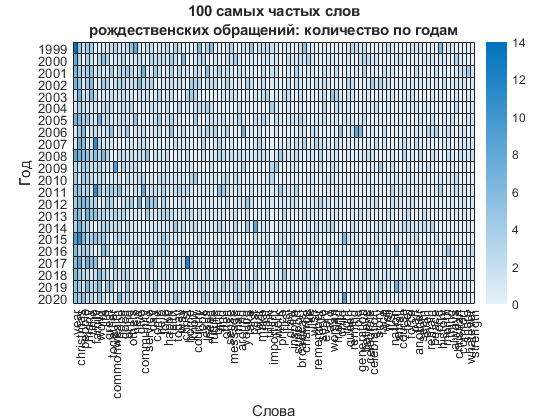

% top 100 words data by years for heat map 
top100 = topkwords(doc_struct.gb.bag, 100);

doc_struct.gb.top100 = top100;

top100_vocab_idx = zeros(100, 1);

for i = 1:100
    top100_vocab_idx(i, 1) = find(doc_struct.gb.bag.Vocabulary == top100.Word(i));
end

heatmap(doc_struct.gb.bag.Counts(:, top100_vocab_idx));
ax=gca;
ax.XData = doc_struct.gb.bag.Vocabulary(top100_vocab_idx);
ax.YData = 1999:2020;

title({'100 самых частых слов', ...
    'рождественских обращений: количество по годам'});

xlabel('Слова');
ylabel('Год');

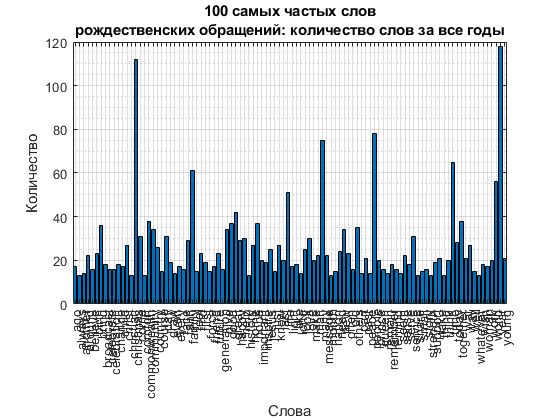


% top 100 words overall
bar(categorical(top100.Word), top100.Count)

grid on;
grid minor;

title({'100 самых частых слов', ...
    'рождественских обращений: количество слов за все годы'});

xlabel('Слова');
ylabel('Количество');

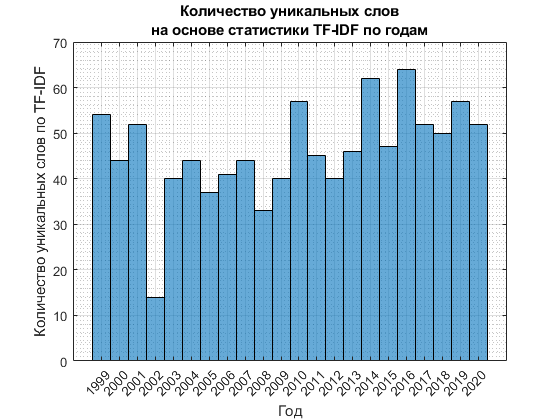

% tf-idf features
tf_idf = tfidf(doc_struct.gb.bag,'TFWeight','binary');

% find elements with max TF-IDF score
[row, col, val] = find(2.5 < tf_idf);

histogram(row, 'BinMethod', 'integers');
xticks(1:22);
xticklabels(1999:2020);

grid on;
grid minor;

xlabel('Год');
ylabel('Количество уникальных слов по TF-IDF');
title({'Количество уникальных слов', ...
    'на основе статистики TF-IDF по годам'})

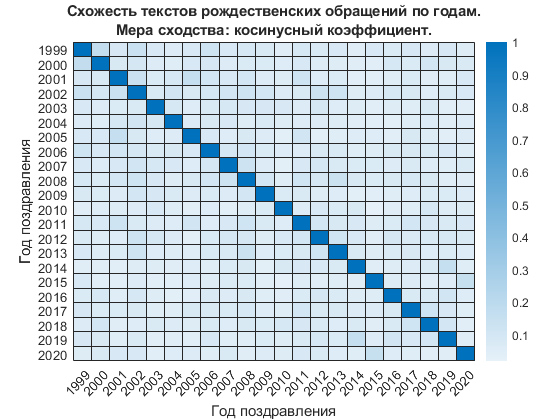

% cosine similarity
cos_sim = cosineSimilarity(doc_struct.gb.bag);

heatmap(cos_sim);
xlabel('Год поздравления');

ylabel('Год поздравления');

ax=gca;
ax.XData = doc_struct.gb.year;
ax.YData = doc_struct.gb.year;

title({'Схожесть текстов рождественских обращений по годам.', ...
    'Мера сходства: косинусный коэффициент.'});

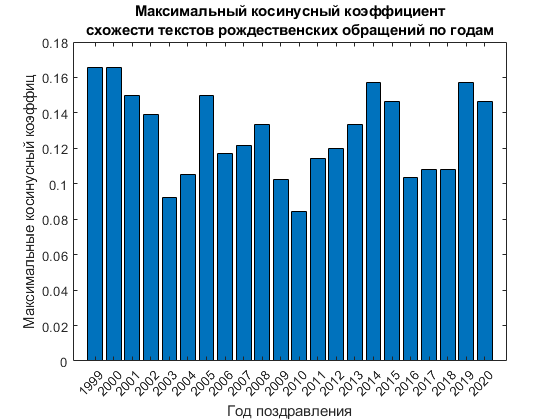


% Периодичность по президентским срокам с максимумом в середине срока
bar(max(cos_sim+diag(repelem(-1,22))))

xticks(1:1:22);
xticklabels(doc_struct.gb.year);

xlabel('Год поздравления');
ylabel('Максимальные косинусный коэффиц');

title({'Максимальный косинусный коэффициент', ...
    'схожести текстов рождественских обращений по годам'});

% Будет ли тот же результат в BM25 и других метриках?

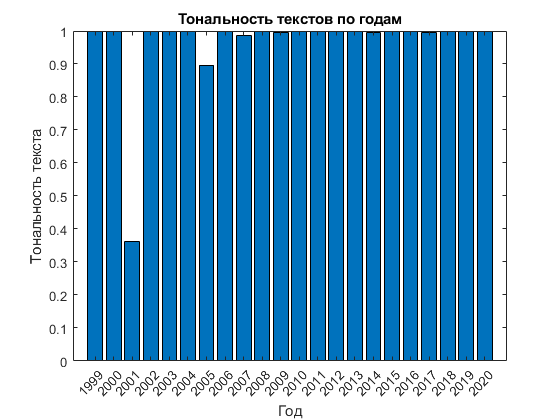

% sentiment analysis
% extremely positive!
sentiment_vader = vaderSentimentScores(doc_struct.gb.tokenized);

% not needed: almost all are equal to 1
%sentiment_ratio = ratioSentimentScores(doc_struct.gb.tokenized);

bar(sentiment_vader);

title('Тональность текстов по годам');

xticks(1:22);
xticklabels(doc_struct.gb.year);

xlabel('Год');
ylabel('Тональность текста');

% summary
%[summary, scores] = extractSummary(doc_struct.gb.tokenized);
%bar(scores);
%join(joinWords(summary)); % ???

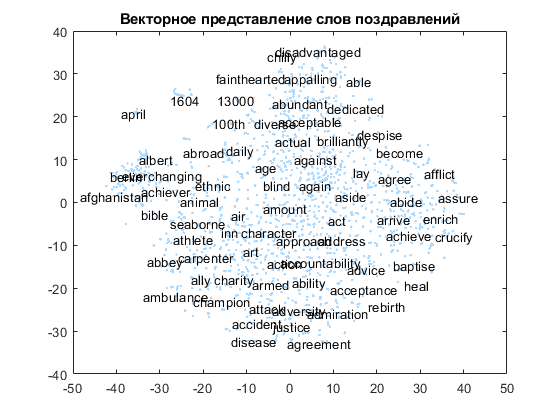

% word embedding with scatter plot
emb = fastTextWordEmbedding;

% missing words in embedding vacabulary
vocab_diff = setdiff(doc_struct.gb.bag.Vocabulary, emb.Vocabulary);

greeting_emb_vocab = setdiff(doc_struct.gb.bag.Vocabulary, vocab_diff);

V = word2vec(emb, greeting_emb_vocab);

XY = tsne(V);

textscatter(XY, greeting_emb_vocab);
title("Векторное представление слов поздравлений");

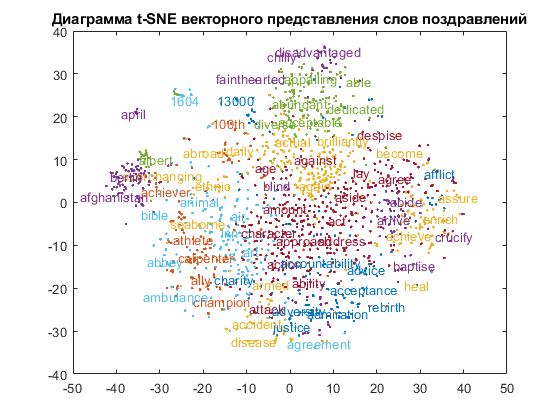

% how to choose k?
% https://medium.com/analytics-vidhya/how-to-determine-the-optimal-k-for-k-means-708505d204eb
cidx = kmeans(V, 25, 'dist','sqeuclidean');

textscatter(XY,greeting_emb_vocab,'ColorData',categorical(cidx));
title("Диаграмма t-SNE векторного представления слов поздравлений");

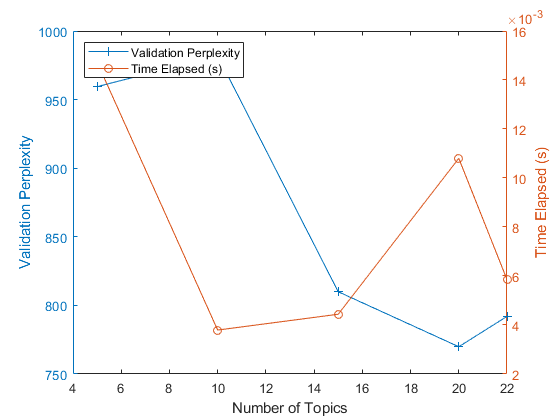

% https://www.mathworks.com/help/textanalytics/ug/choose-number-of-topics-for-LDA-model.html
% number of topics for LDA model

numDocuments = numel(doc_struct.gb.tokenized);
cvp = cvpartition(numDocuments,'HoldOut',0.1);
documentsTrain = doc_struct.gb.tokenized(cvp.training);
documentsValidation = doc_struct.gb.tokenized(cvp.test);

bag = bagOfWords(documentsTrain);
bag = removeInfrequentWords(bag,2);
bag = removeEmptyDocuments(bag);

numTopicsRange = [5:5:20 22];

validationPerplexity = zeros(size(numTopicsRange));
timeElapsed = zeros(size(numTopicsRange));

for i = 1:numel(numTopicsRange)
    numTopics = numTopicsRange(i);
    
    mdl = fitlda(doc_struct.gb.bag,numTopics, ...
        'Solver','savb', ...
        'Verbose',0);
    
    [~,validationPerplexity(i)] = logp(mdl,documentsValidation);
    timeElapsed(i) = mdl.FitInfo.History.TimeSinceStart(end);
end

figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")

yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")

legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','northwest')
xlabel("Number of Topics")


% from graph: 20 topics

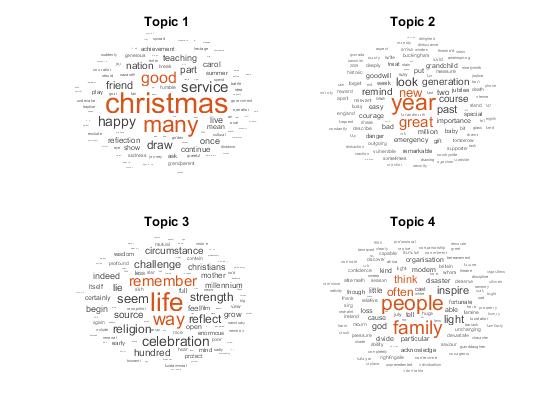

% https://www.mathworks.com/help/textanalytics/ug/analyze-text-data-using-topic-models.html
% fit LDA model

numTopics = 20;
mdl = fitlda(doc_struct.gb.bag, numTopics, 'Verbose', 0);

figure;
for topicIdx = 1:4
    subplot(2,2,topicIdx)
    wordcloud(mdl,topicIdx);
    title("Topic " + topicIdx)
end

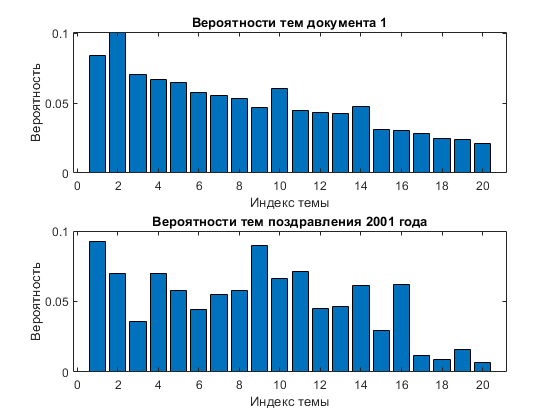

new_document_1 = tokenizedDocument(lower("New York, Washington attack."));
topic_mixture_1 = transform(mdl,new_document_1);

% check topic with 2001 year text
new_document_1_check = doc_struct.gb.tokenized(3);
topic_mixture_1_check = transform(mdl,new_document_1_check);

figure
subplot(2, 1, 1)
bar(topic_mixture_1)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем документа 1")

subplot(2, 1, 2)
bar(topic_mixture_1_check)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем поздравления 2001 года")

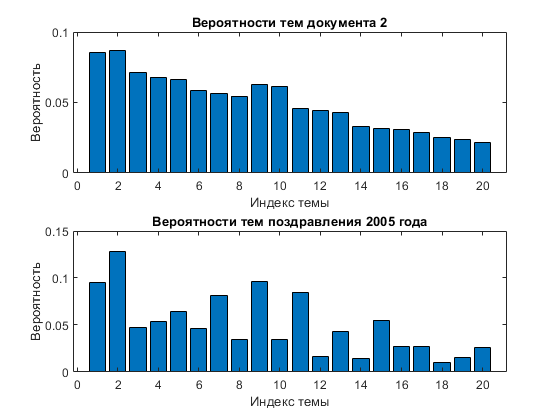


new_document_2 = tokenizedDocument(lower("London attack, tsunami."));
topic_mixture_2 = transform(mdl,new_document_2);

% check topic with 2005 year text
new_document_2_check = doc_struct.gb.tokenized(7);
topic_mixture_2_check = transform(mdl,new_document_2_check);

figure
subplot(2, 1, 1)
bar(topic_mixture_2)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем документа 2")

subplot(2, 1, 2)
bar(topic_mixture_2_check)
xlabel("Индекс темы")
ylabel("Вероятность")
title("Вероятности тем поздравления 2005 года")

% textrank keywords
doc_struct.gb.textrank = textrankKeywords(doc_struct.gb.tokenized, 'MaxNumKeywords', 2);

if 1 < size(doc_struct.gb.textrank.Keyword, 2)
    doc_struct.gb.textrank.Keyword = strip(join(doc_struct.gb.textrank.Keyword));
end

doc_struct.gb.textrank.Keyword

ans = 44×1 string array
    "christmas year year happy new year"
    "christmas new year"
    "world spirituality teaching great faith course"
    "true measure christ influence life"
    "time last year"
    "symbol hope good"
    "life christmas anniversary birth"
    "jubilee year queen"
    "iraq queen christmas broadcast"
    "christmas individual serviceman woman"
    "religious tolerance christmas"
    "culture religion matter"
    "christmas year new year"
    "many terrible year natural"
    "together family community child"
    "faith generation"
    "human family christmas story"
    "story family family"
    "christmas time celebration year"
    "celebration reflection year prince"
    "commonwealth young people new communication"
    "commonwealth organisation"
    "harmony common interest scripture bible bear"
    "walk life agegroups park town city village"
    "nation commonwealth family nation"
    "family adversity new friendship"
    "service others carol bleak"
    

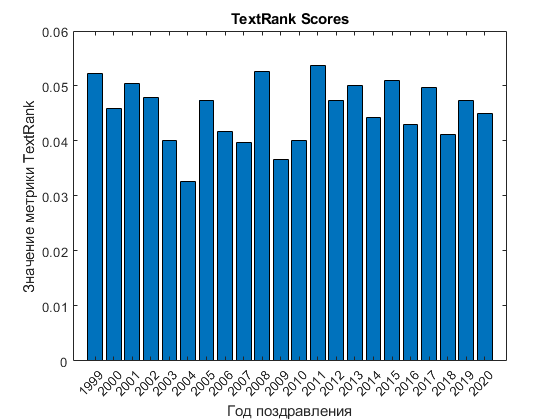


writetable(doc_struct.gb.textrank, 'gb.textrank.xls')

% TextRank Scores
doc_struct.gb.textrank_scores = textrankScores(doc_struct.gb.bag);

figure;
bar(doc_struct.gb.textrank_scores);

xticks(1:22);
xticklabels(doc_struct.gb.year);
xlabel("Год поздравления");
ylabel("Значение метрики TextRank");
title("TextRank Scores");


% rakerank keywords
doc_struct.gb.rakerank = rakeKeywords(doc_struct.gb.tokenized, 'MaxNumKeywords', 2);

if 1 < size(doc_struct.gb.rakerank.Keyword, 2)
    doc_struct.gb.rakerank.Keyword = strip(join(doc_struct.gb.rakerank.Keyword));
end

doc_struct.gb.rakerank.Keyword

ans = 22×1 string array
    "end 1999 queen christmas broadcast look forward start new century new millennium well look lesson history broadcast film white drawing room windsor castle feature film reception young achiever palace holyroodhouse reception member emergency service buckingham palace happy christmas listen choir george chapel windsor remind season carol christmas tree time take stock time reflect event past year make resolution new year ahead december look back just year hundred year thousand year history measure century ever aware tiny part infinite sweep time move century millennium another look future doubt certainty change pace change seem increase true young old mother ninetyninth birthday last august strike inevitability change affect different mother early year compare grandchild many generation future source excitement hope challenge others future cause understandable anxiety many example age amongst vulnerable society worry leave behind sheer rate change seem sweep 